*Lab 7. Event selection optimization You and your lab partner should pick different pT (transverse momentum) samples (one uses low-pT sampels and the other use high-pT samples) for this lab. In each pT sample, there are dedicated training samples for event selection optimization. All studies should be carried out by normalizing Higgs and QCD samples in each pT sample to given expected yields accordingly (See Dataset descriptions).*

clear all; close all; clc;
tic;
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg1 = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd1 = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

*Make a stacked histogram plot for the feature variable: mass*

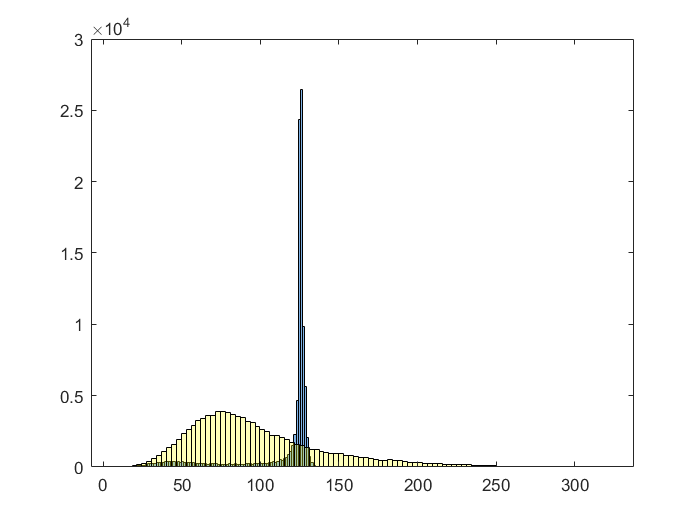

hInvariantMass = higg1(4,:);
histogram(hInvariantMass,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qInvariantMass = qcd1(4,:);
histogram(qInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

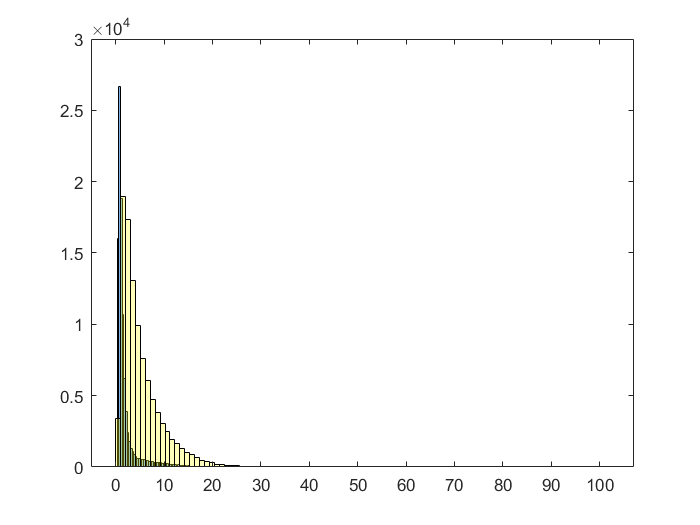

h3to2pointECFratio = higg1(7,:);
histogram(h3to2pointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3to2pointECFratio = qcd1(7,:);
histogram(q3to2pointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

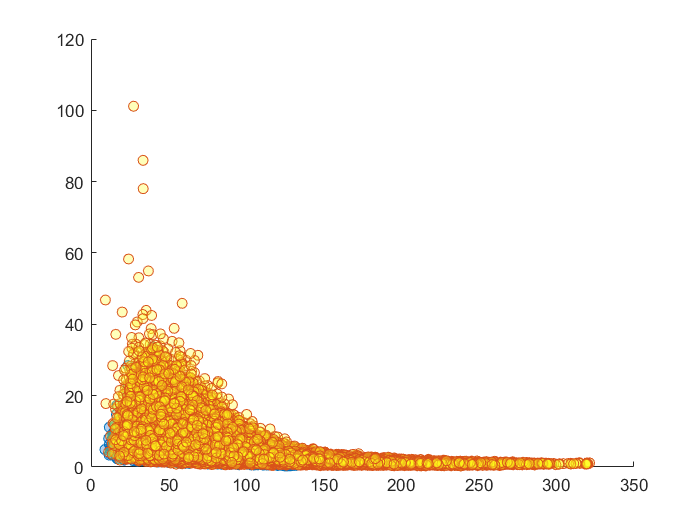

clf;
hold on;
scatter(hInvariantMass,h3to2pointECFratio,'MarkerFaceColor',[0,.4,.8],'MarkerFaceAlpha',0.3)
scatter(qInvariantMass,q3to2pointECFratio,'MarkerFaceColor',[1,1,.1],'MarkerFaceAlpha',0.3)
hold off;

- *Evaluate expected significance without any event selection.*

- *Use Poisson statistics for significance calculation*

- *Compare your number of NHiggs/√(NQCD). If they are equivalent, explain your findings.*

NHiggs/√(NQCD) is not equivalent, therefore explanations of my findings are not required. :)

nHiggs = 100;
nQCD = 2000;
comp3 = nHiggs/sqrt(nQCD)

comp3 = 2.2361

hInvarDist=fitdist(hInvariantMass',"Poisson");
hInvarDistLambda = round(median(hInvariantMass)) %eyeballing lambda due to innacuracy in distribution created since it doesnt exactly follow a poisson distribution.

hInvarDistLambda = 125

qInvariantMassLambda = 75 %eyeballing lambda due to innacuracy in distribution created since it doesnt exactly follow a poisson distribution.

qInvariantMassLambda = 75

Make stacked histogram plots for the reset of features

- Set A of plots without any event selection

- Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)

Comparing Higgs data (in blue) with QCD data (in yellow)

**Transverse momentum:**

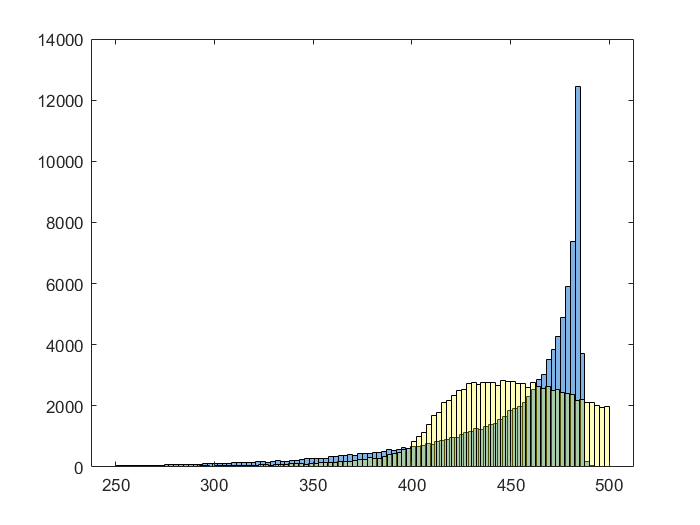

hTransverseMomentum = higg1(1,:);
histogram(hTransverseMomentum,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qTransverseMomentum = qcd1(1,:);
histogram(qTransverseMomentum,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off; 

ratio = 218.1313

cut = 40.8000

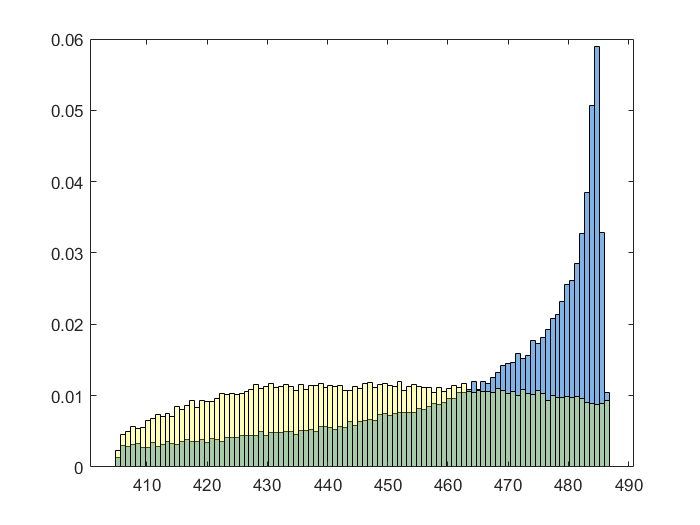

ans =     6.9488   10.4726   11.7846   13.7005   15.6645   17.2503   17.9995   19.2725   20.2637   21.7720   23.1691   24.1803   25.0820   26.1716   26.8837   27.6758   28.2533   29.2510   30.0055   30.9797   31.6489   32.5559   33.2061   34.1473   34.7548   35.4994   36.4368   36.9837   37.6190   38.1741   38.6518   39.2849   39.9519   40.6064   41.2476   41.9337   42.4800   43.0577   43.7570   44.3730   44.4842   45.0359   45.6187   46.0456   46.5831   47.1341   47.5809   47.9100   48.4675   48.8401


massCut4(hTransverseMomentum, qTransverseMomentum,446,483)

**Pseudorapidity**

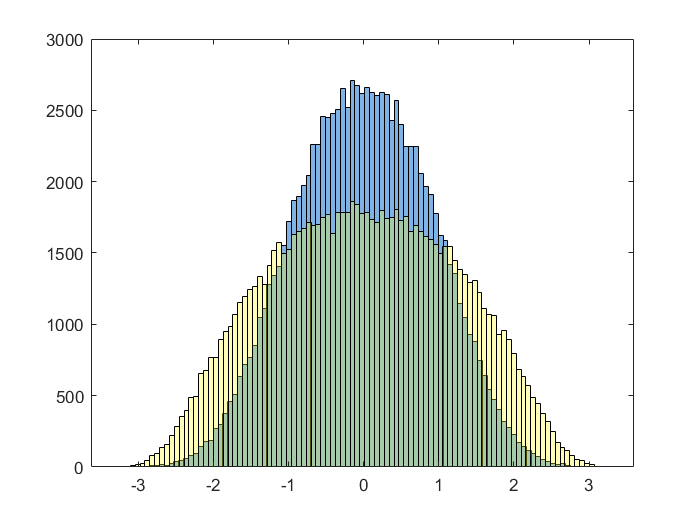

hPseudorapidity = higg1(2,:);
histogram(hPseudorapidity,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qPseudorapidity = qcd1(2,:);
histogram(qPseudorapidity,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Azimuthal angle**

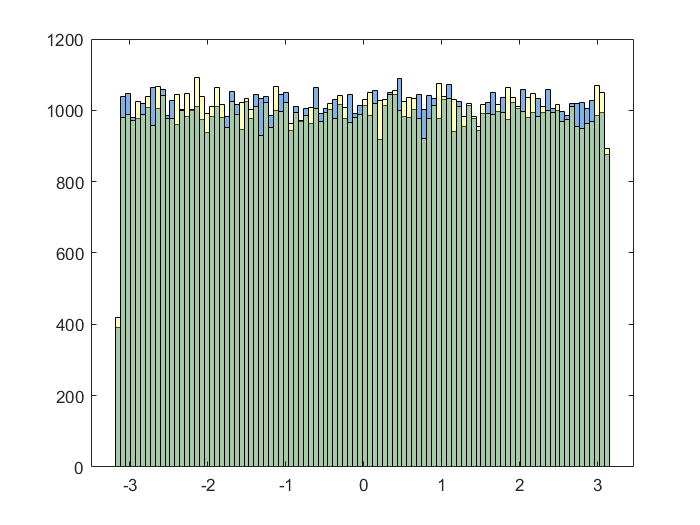

hAzimuthAngle = higg1(3,:);
histogram(hAzimuthAngle,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qAzimuthAngle = qcd1(3,:);
histogram(qAzimuthAngle,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Invariant masses**

hInvariantMass = higg1(4,:);
histogram(hInvariantMass,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qInvariantMass = qcd1(4,:);
histogram(qInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

ratio = 230.1943

cut = 1.2000

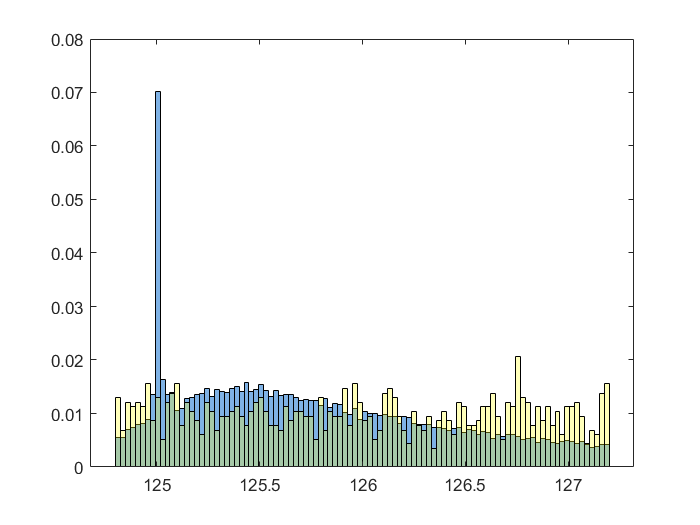

[ratios, cut, hInvarMassCut1, invarMassRatioPostCut1, qInvarMassCut1] = massCut4(hInvariantMass,qInvariantMass,126,75);

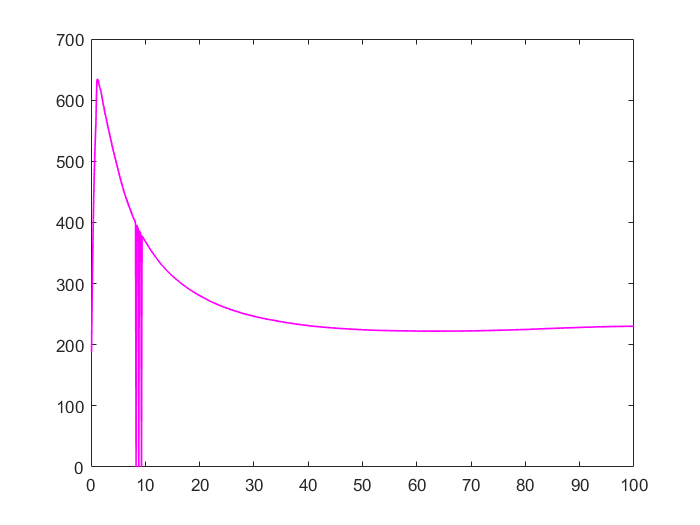

x = 0.1:0.1:100;
plot(x,ratios,"Linewidth", 1, "Color",[1 0 1])

ratio = 0

cut = 0.1000

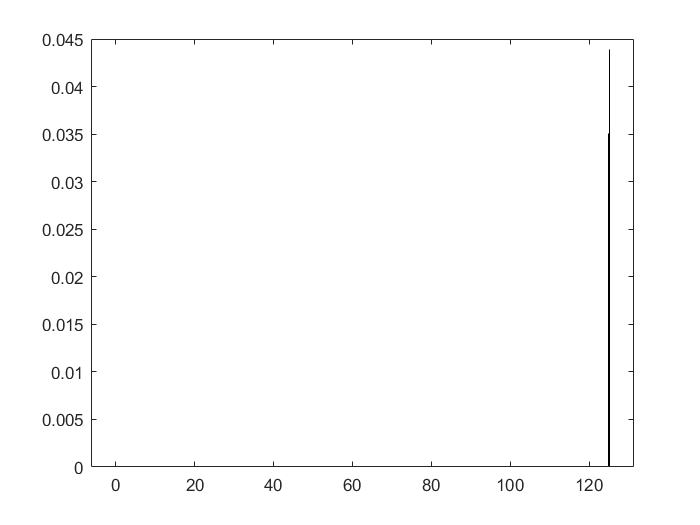

[ratios, cut, invarMassRatioPostCut2, hCut2, qCut2] = massCut4(hInvarMassCut1,qInvarMassCut1,125.05,120.35);

hInvarAvg = mean(hInvariantMass)

hInvarAvg = 114.8924

hInvarSTD = std(hInvariantMass)

hInvarSTD = 25.3511

qInvarAvg = mean(qInvariantMass)

qInvarAvg = 97.7380

qInvarSTD = std(qInvariantMass)

qInvarSTD = 43.4929

STD is large and skewed due to some higgs picked up on the left side of the graph, and this distribution is not a normal distribution so the STD is not very useful. 

Using the range of 120-132 which is where the spike appears to be, we created a list of the indices of the QCD data points where that mass range is within that spike.

newIndex(1) = 0;
newLength = 1;
for i=1:length(qInvariantMass)
    if (qInvariantMass(i) > 120 && qInvariantMass(i) < 132)
        newIndex(newLength) = i;
        newLength = newLength +1;
    end
end

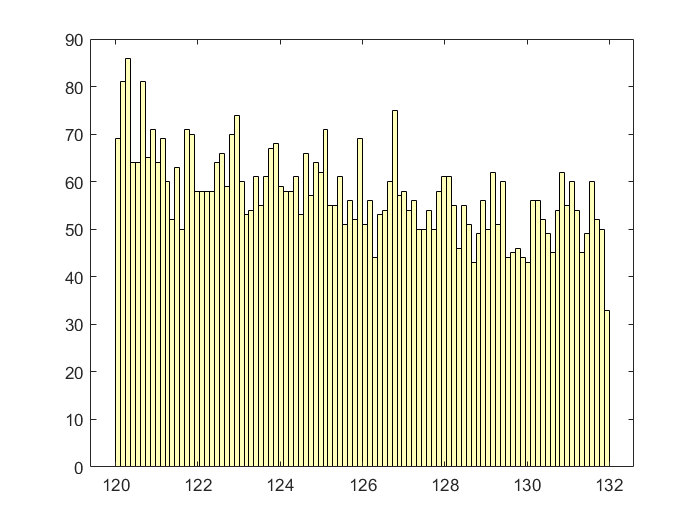

newQInvariantMass = qInvariantMass(newIndex);
histogram(newQInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)

**2 point ECF ratio (2PECFR)**

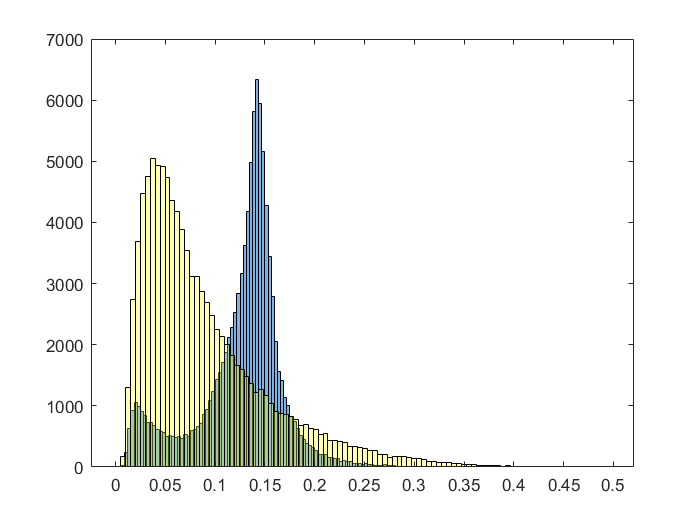

h2PointECFratio = higg1(5,:);
histogram(h2PointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q2PointECFratio = qcd1(5,:);
histogram(q2PointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

ratio = 223.6068

cut = 0.3000

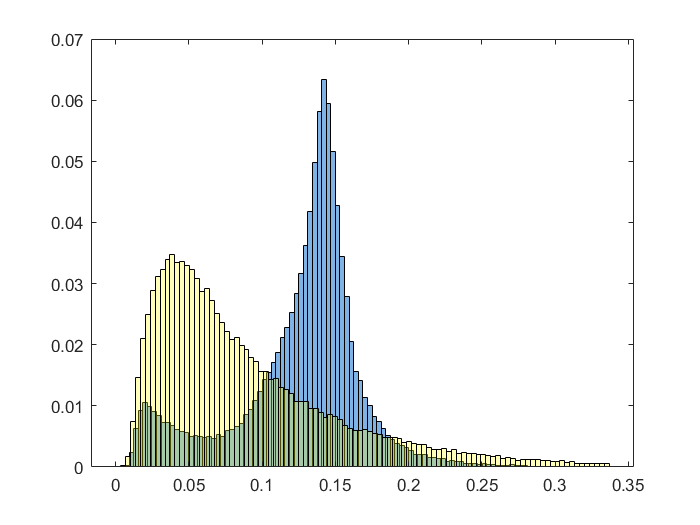

massCut4(h2PointECFratio,q2PointECFratio,0.037,0.141);

**3 point ECF ratio (3PECFR)**

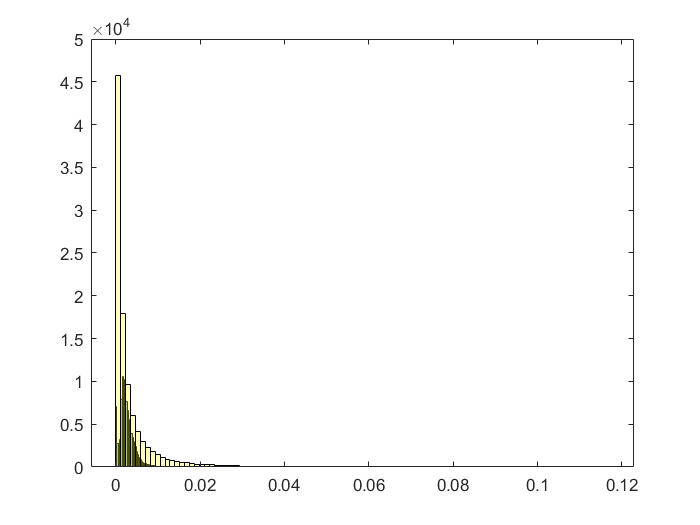

h3PointECFratio = higg1(6,:);
histogram(h3PointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3PointECFratio = qcd1(6,:);
histogram(q3PointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**3 to 2 point ECF ratio (3-2PECFR)**

h3to2pointECFratio = higg1(7,:);
histogram(h3to2pointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3to2pointECFratio = qcd1(7,:);
histogram(q3to2pointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

ratio = 223.6079

cut = 0.7000

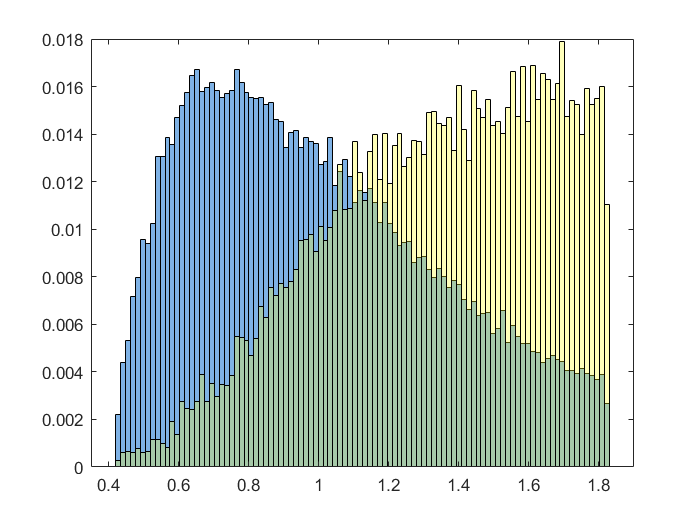

ratios =   153.2692  216.9774  268.6456  315.1405  354.4078  382.4198  390.4756  382.9443  373.0819  363.9424  356.0569  348.7063  341.6047  335.1491  329.0224  323.6175  318.3252  313.3134  308.8560  304.6980  300.9513  297.3605  294.0123  290.9688  288.0937  285.2926  282.8255  280.2089  277.6204  275.2981  273.1853  271.0749  269.3320  267.5292  265.8798  264.2673  262.7029  261.3073  259.8732  258.5728  257.4675  256.2457  255.1619  254.1071  253.1760  252.1291  251.2261  250.2340  249.4291  248.5852


cut = 0.7000

has =     1.2980    1.4456    0.9866    1.2185    1.2918    0.4344    0.9312    0.9494    0.5540    0.6896    0.6928    0.8326    0.6468    1.6798    0.7978    0.6508    1.1959    1.5013    0.5900    0.7593    1.1409    1.1227    0.6451    1.6013    0.5226    0.9355    0.6936    0.9285    1.0034    0.6822    1.2039    0.7712    0.5503    1.1165    0.7556    0.6122    1.0637    0.6881    0.7931    1.2398    1.5176    0.6629    0.6181    0.5281    0.8417    1.7488    1.1970    1.2547    1.2789    0.7688


qas =     1.5321    1.7699    1.1043    1.7348    0.5354    1.5511    1.2350    0.9791    1.6946    1.7703    0.9559    1.4316    1.1540    1.3950    1.7612    1.3954    1.7893    1.3007    1.7448    1.6120    1.1687    0.9222    0.8265    1.1857    1.5893    1.5007    1.7861    1.4769    1.2228    1.7483    1.4452    1.5313    1.7167    1.6749    0.6573    1.7267    1.1199    1.4597    1.8248    0.9082    1.2914    1.8075    1.4647    1.6626    1.3894    0.8707    0.9990    1.0227    1.6082    1.5287


[ratios, cut, has, qas] = massCut4(h3to2pointECFratio,q3to2pointECFratio,median(h3to2pointECFratio),median(h3to2pointECFratio))

**Angularity:**

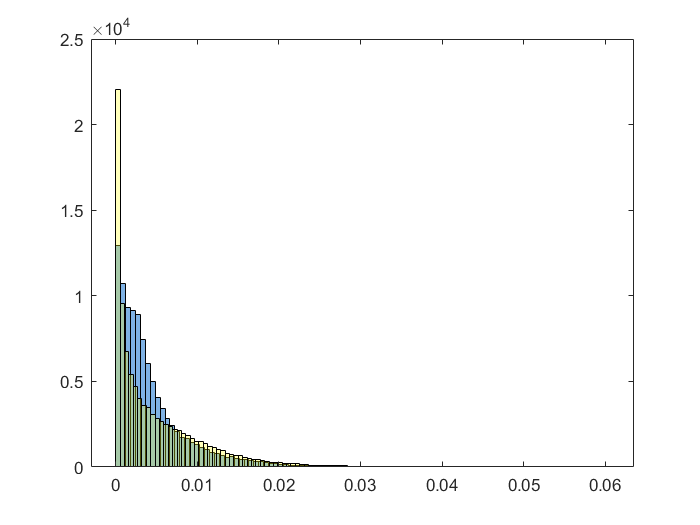

hAngularity = higg1(8,:);
histogram(hAngularity,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qAngularity = qcd1(8,:);
histogram(qAngularity,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

**Variable 9:**

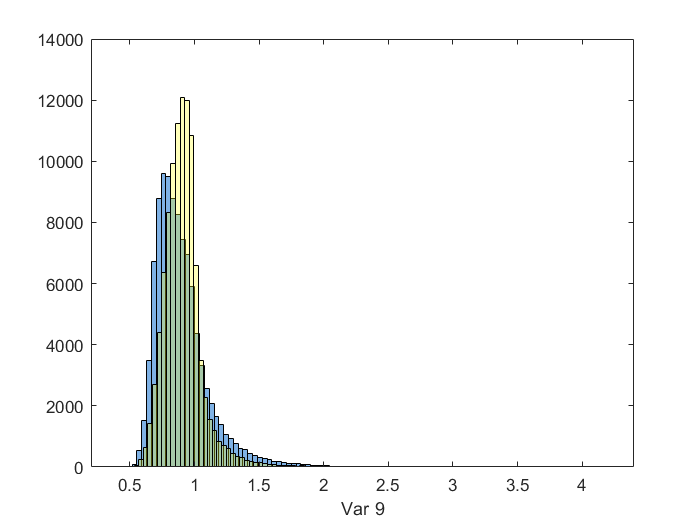

hvar9 = higg1(9,:);
histogram(hvar9,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 9'
hold on
qvar9 = qcd1(9,:);
histogram(qvar9,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 10**

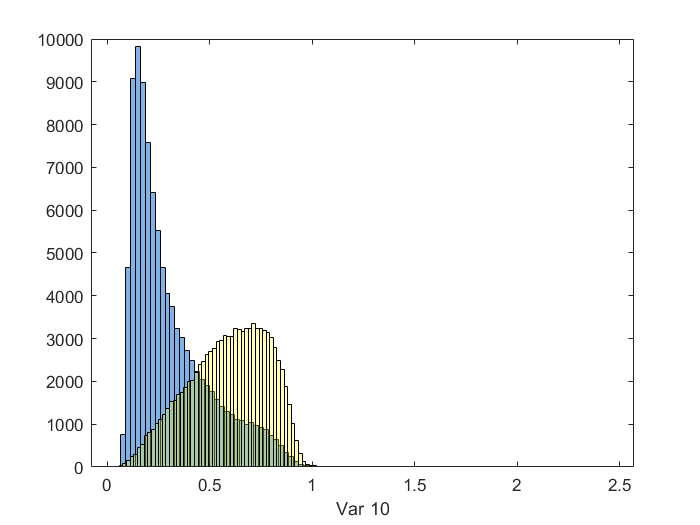

hvar10 = higg1(10,:);
histogram(hvar10,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 10'
hold on
qvar10 = qcd1(10,:);
histogram(qvar10,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 11**

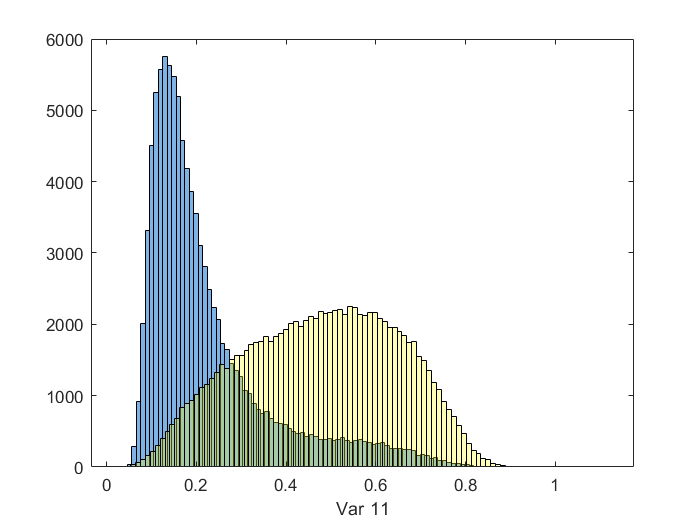

hvar11 = higg1(11,:);
histogram(hvar11,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 11'
hold on
qvar11 = qcd1(11,:);
histogram(qvar11,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

ratio = 223.6068

cut = 0.5000

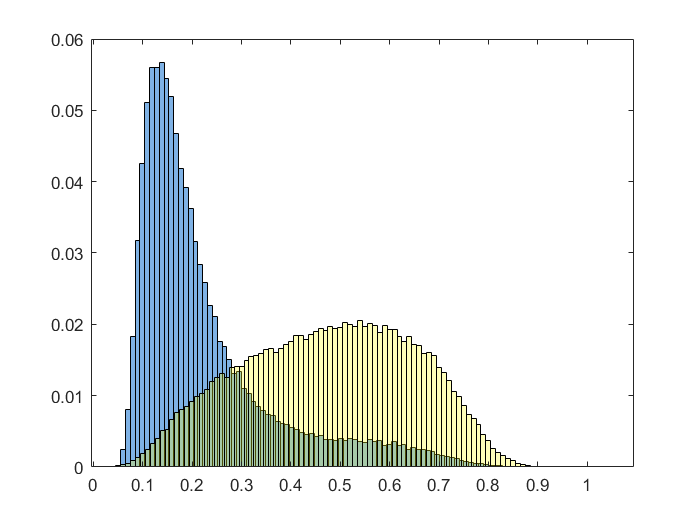

massCut4(hvar11,qvar11,0.55,0.15);

**Variable 12**

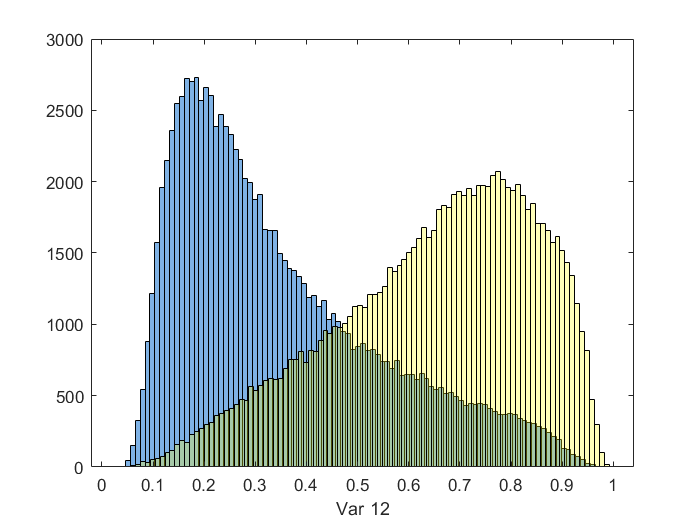

hvar12 = higg1(12,:);
histogram(hvar12,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 12'
hold on
qvar12 = qcd1(12,:);
histogram(qvar12,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 13**

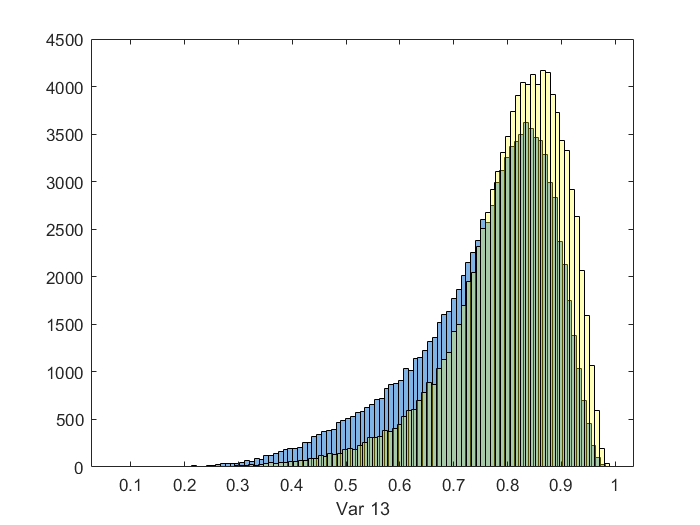

hvar13 = higg1(13,:);
histogram(hvar13,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 13'
hold on
qvar13 = qcd1(13,:);
histogram(qvar13,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

**Variable 14**

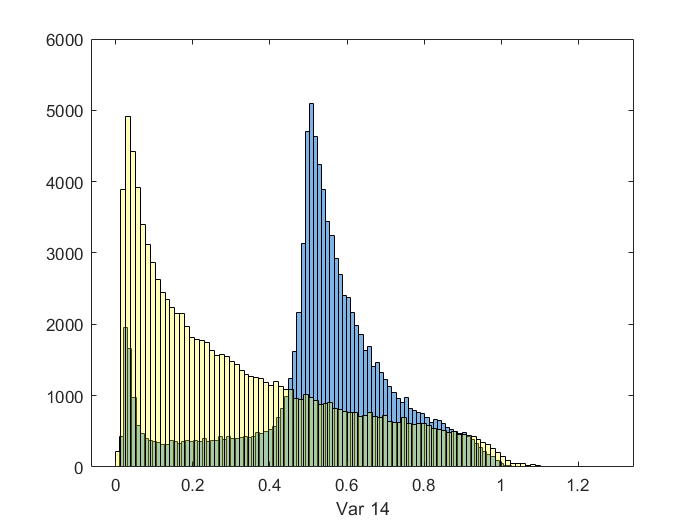

hvar14 = higg1(14,:);
histogram(hvar14,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 14'
hold on
qvar14 = qcd1(14,:);
histogram(qvar14,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

Lab 8. Pseudo-experiment data analysis Using your optimized event selection, hunt for your signal by using one of the pseduo-experiment dataset. For each task below, you will choose one of the observed data from your specific pT sample to perform the analysis.

tic;
h5disp("data_highLumi_pt_250_500.h5")
highLumi = h5read("data_highLumi_pt_250_500.h5",'/data/block0_values');
h5disp("data_lowLumi_pt_250_500.h5")

HDF5 data_highLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes

lowLumi = h5read("data_lowLumi_pt_250_500.h5",'/data/block0_values');

- High luminosity data

- Focus on each feature of your event selection.

- Plot observed data, overlap with expected signal and background (normalized to observed yields) without event selection.

highLumiMass = highLumi(4,:);

HDF5 data_lowLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes:


[C_higgs, Cen_higgs] = hist(hInvariantMass, 100);
[C_qcd, Cen_qcd] = hist(qInvariantMass,100);

l = length(highLumiMass)

C_higgs = C_higgs./sum(C_higgs).*100/20000*l;
C_qcd = C_qcd./sum(C_qcd).*100/20100*l;

histogram(highLumiMass,100, 'FaceColor',[0 0 0], 'FaceAlpha', 0.1)
hold on

l = 40344

bar(Cen_qcd,C_qcd,'FaceColor',[0 1 0], 'FaceAlpha',.3)
bar(Cen_higgs,C_higgs,'FaceColor',[0 0 1], 'FaceAlpha',.7)
legend('highLumi','qcd','higgs')
hold off

- Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.

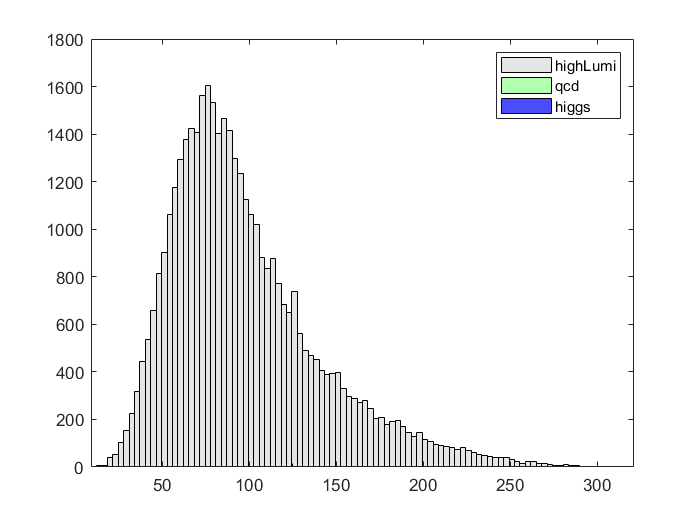

highLumiMass = highLumi(4,:);

[C_higgs, Cen_higgs] = hist(hInvarMassCut1, 100);
[C_qcd, Cen_qcd] = hist(qInvarMassCut1,100);

l = length(highLumiMass)


C_higgs = C_higgs./sum(C_higgs).*100/20000*l;
C_qcd = C_qcd./sum(C_qcd).*100/20100*l;

histogram(highLumiMass,100, 'FaceColor',[0 0 0], 'FaceAlpha', 0.1)
hold on
bar(Cen_qcd,C_qcd,'FaceColor',[0 1 0], 'FaceAlpha',.3)
bar(Cen_higgs,C_higgs,'FaceColor',[0 0 1], 'FaceAlpha',.7)
legend('highLumi','qcd','higgs')

l = 40344

hold off

- Evaluate observed significance and compare your results to expectation

         2. Low luminosity data

- Focus on each feature of your event selection.

- Plot observed data, overlap with expected signal and background (normalized to observed yields) without event selection.

- Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.

- Evaluate observed significance and compare your results to expectation

lowLumiMass = lowLumi(4,:);

[C_higgs, Cen_higgs] = hist(hInvariantMass, 100);
[C_qcd, Cen_qcd] = hist(qInvariantMass,100);

l = length(lowLumiMass)

C_higgs = C_higgs./sum(C_higgs).*100/20000*l;
C_qcd = C_qcd./sum(C_qcd).*100/20100*l;


histogram(lowLumiMass,100, 'FaceColor',[0 0 0], 'FaceAlpha', 0.1)
hold on
bar(Cen_qcd,C_qcd,'FaceColor',[0 1 0], 'FaceAlpha',.3)
bar(Cen_higgs,C_higgs,'FaceColor',[0 0 1], 'FaceAlpha',.7)
legend('lowLumi','qcd','higgs')
hold off

- 95% Confidence Level of signal yields

- In the low luminosity data, the observed significance is less than 5σ. We will calculate the 95% confidence level upper limit of signal yield.

- Evaluate the expected 95\% confidence level upper limit

- Evaluate the observed 95\% confidence level upper limit

- Compare expectation to observation. Comment on your finding.

- Bonus:

- Evalute the 1σσ uncertainty of the expected 95\% confidence level upper limit.

l = 4060

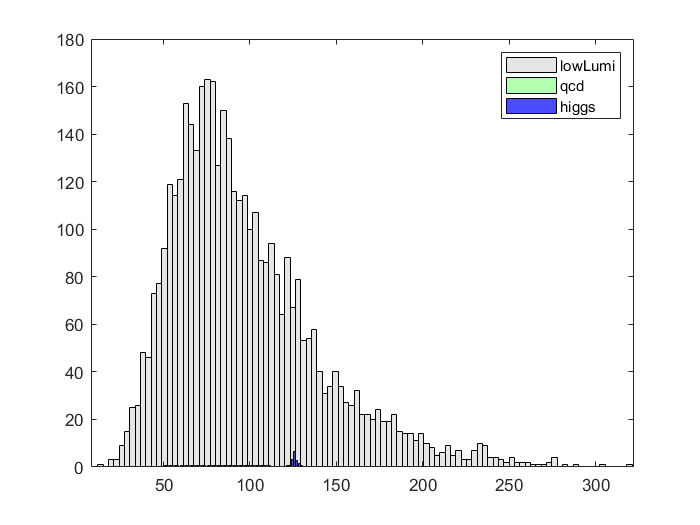

Elapsed time is 5.122983 seconds.


toc;